clc, clear

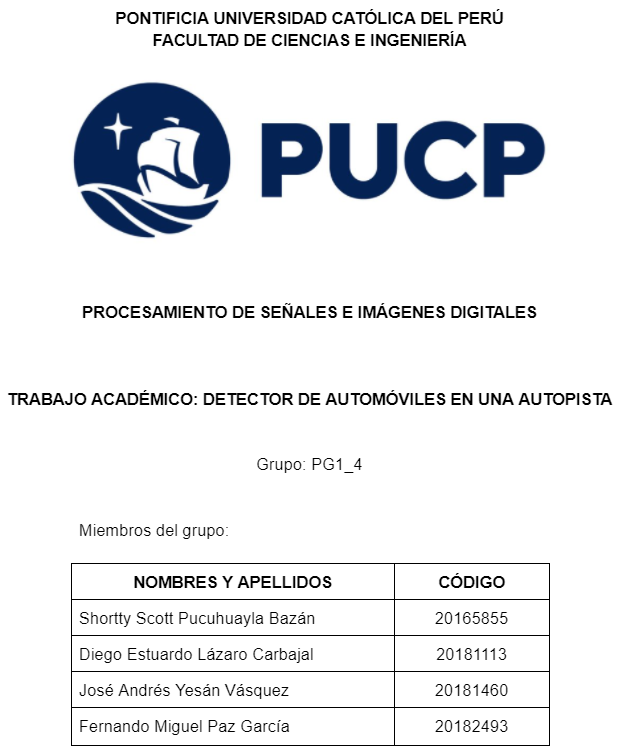

***Introducción***

El presente trabajo busca utilizar e implementar las diversas técnicas de detección de imágenes aprendidas en el curso, para la detección específica de vehículos en movimiento de una cámara de tránsito ubicada en cierta autopista, la cual es transitada muy a menudo por diversos tipos de vehículos. Esto se implementará por medio de la aplicación MatLab, con la cual se ha venido trabajando a lo largo del curso.

***Detección de Frames de video***

En esta sección utilizamos funciones propias de MatLab para la lectura del video de prueba el cual contiene la autopista con vehiculos que se analizará. Luego de esto, manualmente se selcciona un frame específico del video, el cual contiene la autopista vacía. Esto permitirá encontrar el fondo posible de la imagen, la cual asu vez, permitira la detección posterior de de vehículos.

video = VideoReader('RoadTrafficVideo1.mp4');
%implay('RoadTrafficVideo1.mp4')
pista = read(video, 335);
pista = pista(64:144,:,:);
%pista = read(video, 823);
%pista = pista(91:240,1:150,:);

***Generación de máscaras y reporte Vehícular***

Luego, detectamos el número total de frames o imagenes que posee le video y generamos algunas máscaras que serán utiles para el preprocesamiento de imagenes analizadas. En este caso, dada la baja resolución del video, conviene utilizar un filtro gaussiano que permita atenuar el ruido de la imagen, además se genera una máscara en forma de disco para la futura dilatacion y cerrado de las imagenes. 

n = video.NumFrames;
k = fspecial('gaussian', 7, 3);
se = ones(11, 5);
se2 = strel('disk',4, 0);

reporte = zeros(1,n)

***Etapa de analisis iterativo de cada frame***

Debido a que en escencia el video es una sucesión de imagenes o frames, es conveniente utilizar una estructura iterativa que permita un anlisis repetitivo en cada imagen del video. luego de esto, se seleciona el frame actual del video, se realiza la resta de vlaores de pixeles del frame actual con el fondo previamente selccionado y se umbraliza la imagen. Esto da como resultado una miagne en escala de grises de todas a las secciones diferente al fondo, luego se le aplica el filtro gaussiano para atenuar las difuminaciones y se vuelve a umbralizar. Finalmente, la imagen queda con ciertas secciones de pixeles "esparcidos" que no relfejjan información signicativa o relevante, por lo que conviene 

for i = 2:n
    
    autos = read(video, i);
    autos = autos(64:144,:,:);
    I2 = sum(abs(double(autos) - double(pista)), 3);
    mask1 = I2 > 110;
    
    bmf = filter2(k, mask1);
    bm2 = bmf > 0.75;
    
    dil1 = imdilate(bm2, se);
    autos1 = imclose(dil1, se2);
    
    pause(0.05)  

***Extracción de Información de Resutado de Detección    ***

     L = bwlabel(autos1); 
    
    info = regionprops(autos1, 'Centroid', 'BoundingBox', 'Eccentricity');
    
    n_blobs = max(L(:));
    
    for ind = n_blobs:-1:1 
      if info(ind).Eccentricity > 0.95
        info(ind) = []; 
      end
    end
    n_autos = length(info);
    %subplot(1,2,1), 
    imshow(autos);
    %subplot(1,2,1),
    contador=0;
    for ind = 1:n_autos
        if info(ind).BoundingBox (4)>15
            rectangle('Position', info(ind).BoundingBox,'EdgeColor','b', 'LineWidth', 1)
            contador=contador+1;
        end
    end

    ***Generación del reporte final de detecció vehicular***

    
    %info(ind).BoundingBox  
    reporte(1,i)=contador;
end
plot(reporte)

